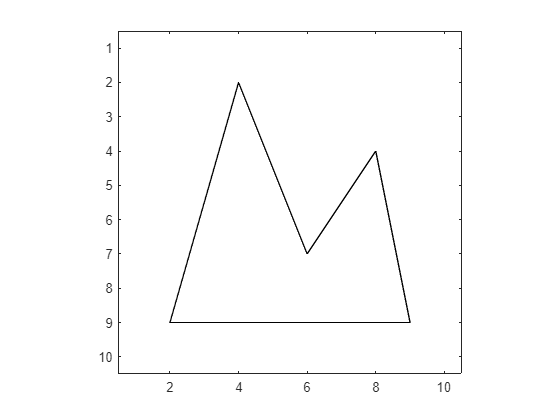

X = [2, 9, 8, 6, 4];
Y = [9, 9, 4, 7, 2];
colour = [0 ; 0 ; 255] / 255;
img = ones(10, 10, 3);

image(img)
hold on
plot([X, X(1)], [Y, Y(1)], 'k-') 
hold off
axis equal tight

img = drawpolygon(img, X, Y, colour);


y = 2

ET
       x    N  xstep  dx   dy  ymin ymax 
e1 : [ 8    0    1    1    5    4    9  ]
e2 : [ 8    0   -1    2    3    4    7  ]

AET
       x    N  xstep  dx   dy  ymin ymax 
e1 : [ 4    0    1    2    5    2    7  ]
e2 : [ 4    0   -1    2    7    2    9  ]

Fill pixels (4,2) to (4,2), 

Update AET

AET
       x    N  xstep  dx   dy  ymin ymax 
e1 : [ 4    2    1    2    5    2    7  ]
e2 : [ 4    2   -1    2    7    2    9  ]

y = 3

ET
       x    N  xstep  dx   dy  ymin ymax 
e1 : [ 8    0    1    1    5    4    9  ]
e2 : [ 8    0   -1    2    3    4    7  ]

AET
       x    N  xstep  dx   dy  ymin ymax 
e1 : [ 4    2    1    2    5    2    7  ]
e2 : [ 4    2   -1    2    7    2    9  ]

Fill pixels (4,3) to (4,3), 

Update AET

AET
       x    N  xstep  dx   dy  ymin ymax 
e1 : [ 4    4    1    2    5    2    7  ]
e2 : [ 4    4   -1    2    7    2    9  ]

y = 4

AET
       x    N  xstep  dx   dy  ymin ymax 
e1 : [ 4    4    1    2    5    2    7  ]
e2 : [ 4    4   -1    

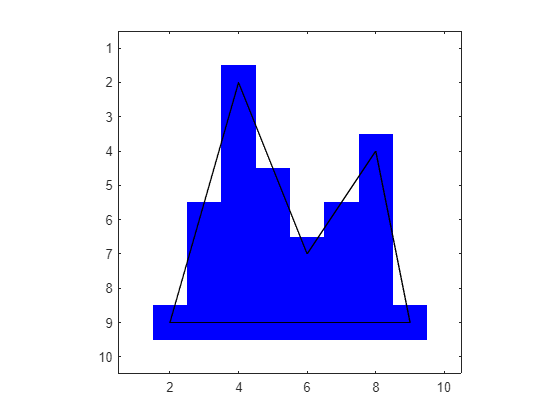

image(img)
hold on
plot([X, X(1)], [Y, Y(1)], 'k-') 
hold off
axis equal tight

function R = drawpolygon(R, X, Y, colour)

% Generate edge table
n = length(X);
ET = [];
for i = 1 : n
    j = 1 + mod(i, n);
    if Y(i) < Y(j)
        imin = i;
        imax = j;
    elseif Y(i) > Y(j)
        imin = j;
        imax = i;
    else
        continue
    end

    dx = X(imin) - X(imax);
    dy = Y(imin) - Y(imax);
    if dx > 0
        xstep = -1;
    elseif dx < 0
        xstep = 1;
    end
    ET = [ET ; X(imin), 0, xstep, abs(dx), abs(dy), Y(imin), Y(imax) ];
end

% Loop through scanlines
y = min(Y);
AET = [];
n = 1;
while isempty(ET) == 0 || isempty(AET) == 0
    
    % Move edges from ET to AET
    i = 1;
    while i <= size(ET,1)
        if ET(i,6) == y
            AET = [ AET ; ET(i,:) ];
            ET(i,:) = [];
        else
            i = i + 1;
        end
    end
    fprintf('\ny = %1i\n', y)
    printET(ET, 'ET')
    printET(AET, 'AET')

    % Sort AET by x value
    sortedAET = sortrows(AET, 1);
    if isequal(AET,sortedAET) == 0
        AET = sortedAET;
        fprintf('\nSort AET')
        printET(AET, 'AET')
    end

    % Fill scanline
    i = 1;
    fprintf('\nFill pixels ')
    while i < size(AET,1)
        fprintf('(%1i,%1i) to (%1i,%1i), ', AET(i,1), y, AET(i+1,1), y)
        for x = AET(i,1) : AET(i+1,1)
            R(y,x,:) = colour;
        end
        i = i + 2;
    end

    % Remove edges from AET
    i = 1;
    while i <= size(AET,1)
        
        % Update N and x
        AET(i,2) = AET(i,2) + AET(i,4);
        while AET(i,2) >= AET(i,5)
            AET(i,2) = AET(i,2) - AET(i,5);
            AET(i,1) = AET(i,1) + AET(i,3);
        end

        % Remove edges from AET whose ymax = y
        if AET(i,7) == y
            AET(i,:) = [];
        else
            i = i + 1;
        end    
    end
    if size(AET,1) > 0
        fprintf('\n\nUpdate AET\n')
        printET(AET, 'AET')
    end

    % Incremement y
    y = y + 1;
    
end

end

function printET(ET, label)

if size(ET, 1) == 0
    return
end
fprintf('\n%s\n', label)
fprintf('       x    N  xstep  dx   dy  ymin ymax \n')
for i = 1 : size(ET, 1)
    fprintf('e%1i : [ %1i %4i %4i %4i %4i %4i %4i  ]\n', i, ET(i,:))
end

end